# **TU: SVM classification**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

mod: 2024-2

## Introduction

Classification with SVM

## Example: Circular Distribution

### Dataset 1:  Random Generation for Circular Distribution

rng(1); % For reproducibility

% Class y=-1
r = sqrt(1.1*rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
% Class y=1
r2 = sqrt(3*rand(100,1)+0.9); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

dataC = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

### Train SVM 

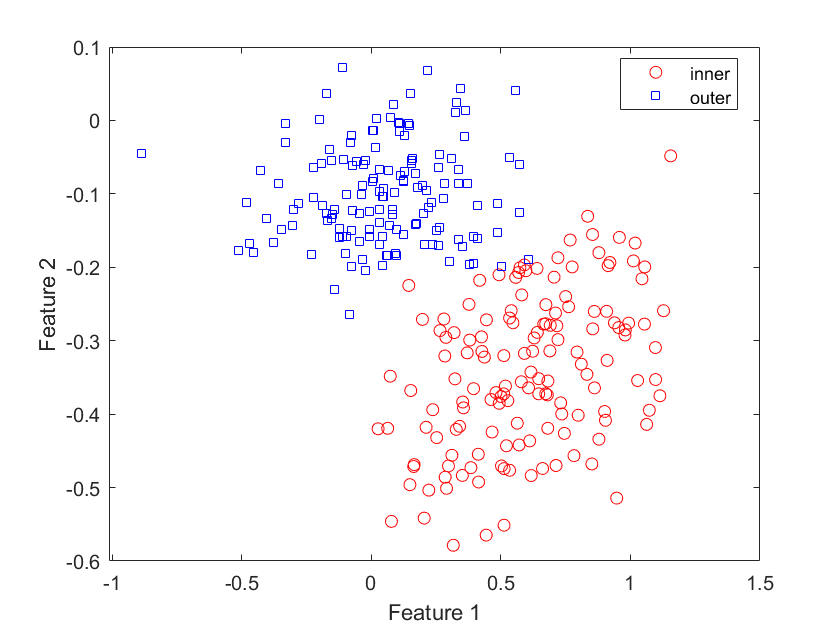

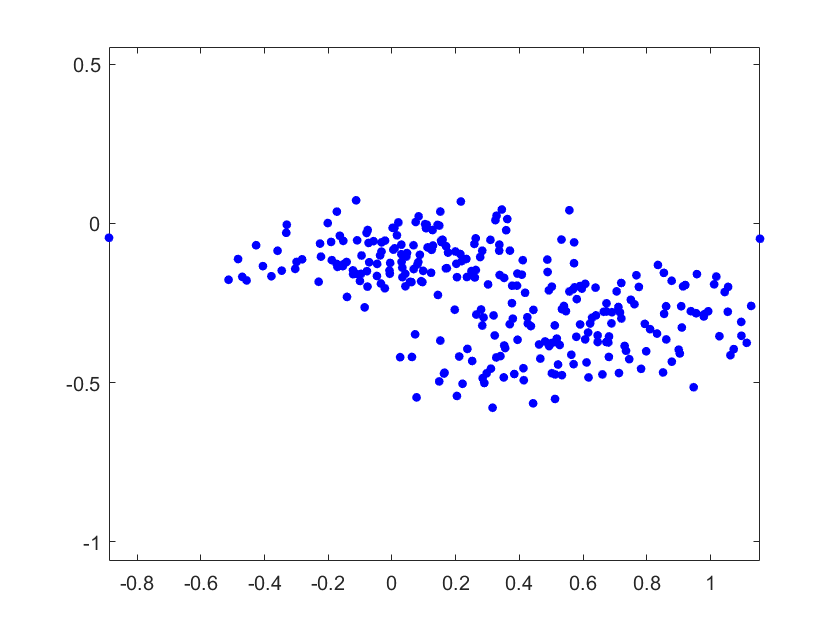

% With Box Constraint =inf
cl = fitcsvm(dataC,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);



% With Box Constraint default - Also check the result
% cl = fitcsvm(dataC,theclass,'KernelFunction','rbf');


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

cv = K-겹 교차 검증 분할
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28

**Confusion matrix** on the training set

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(theclass,mlClass);


**Predict scores over the grid**

d = 0.02;

mlResubErr = 0.0313

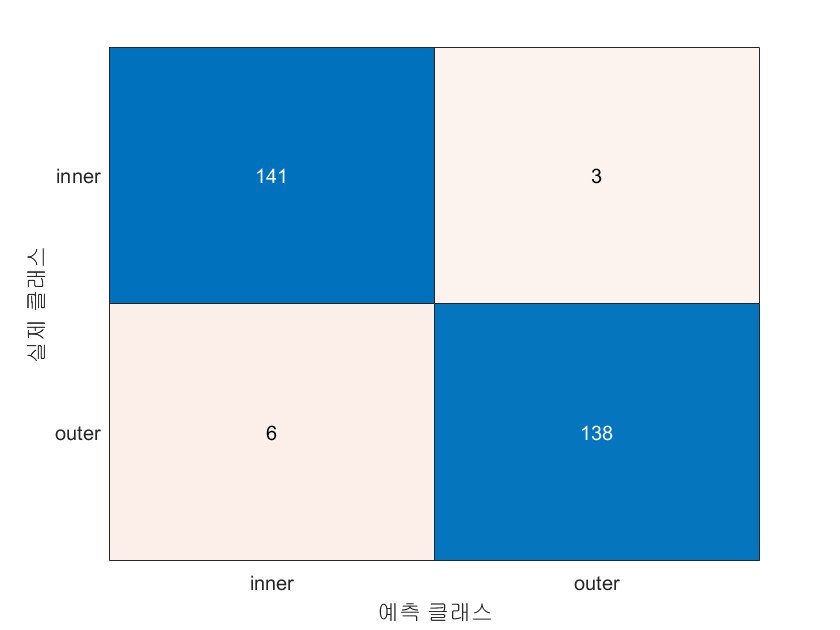

[x1Grid,x2Grid] = meshgrid(min(dataC(:,1)):d:max(dataC(:,1)),...
    min(dataC(:,2)):d:max(dataC(:,2)));

xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

figure;
h(1:2) = gscatter(dataC(:,1),dataC(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(dataC(cl.IsSupportVector,1),dataC(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(theclass,'KFold',10)  %k-fold

cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

# Exercise  

## Exercise 1: SVM Classification with CWRU (binary class)

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- For binary class:  Outer and Inner Race Fault

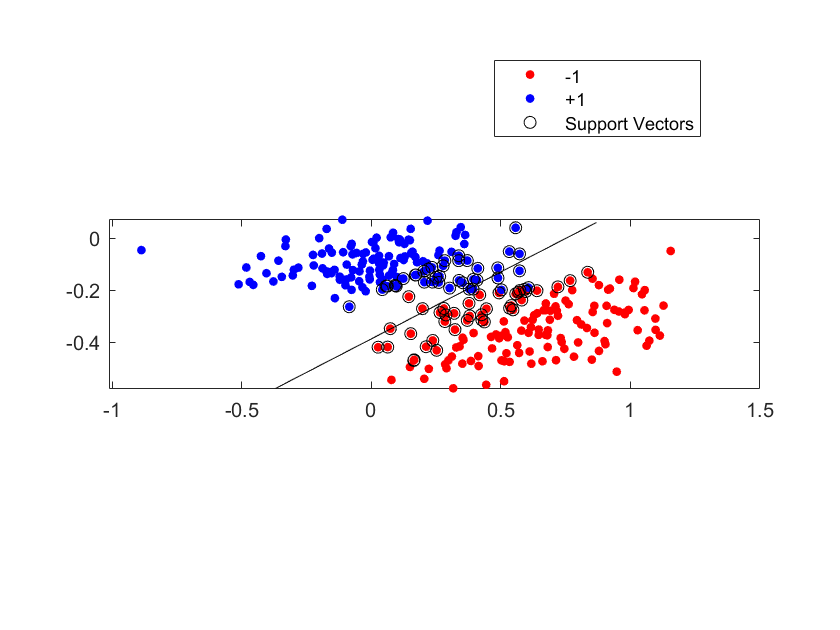

clear


% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor

cp = K-겹 교차 검증 분할
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28

Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));


mlCVErr = 0.0313

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
N = size(X,1);

% Plot
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

### **CV Partition**

% cvpartition to generate k=10 disjoint stratified subsets.

%%% YOUR CODE GOES HERE
% cv = _________________

###  Train SVM 

%%% YOUR CODE GOES HERE
% specifiy class name:  fitcsvm(..., 'ClassNames',{'outer','inner'})
% cl = ______________



### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

%%% YOUR CODE GOES HERE


**Confusion matrix** on the training set

%%% YOUR CODE GOES HERE



**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on
h(3) = plot(X(cl3.IsSupportVector,1),X(cl3.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

%%% YOUR CODE GOES HERE


Cross validate and show cv loss

%%% YOUR CODE GOES HERE


## Exercise 2: SVM Classification with CWRU (3 classes)

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

% Example
% X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
% X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
% X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Analyze  the test and train results 

% Your code goes here
% Your code goes here

Compare performance of SVM with  other models such as Logistic Regression